**The cart and pole system**

Consider the cart-and-pole system here depicted:

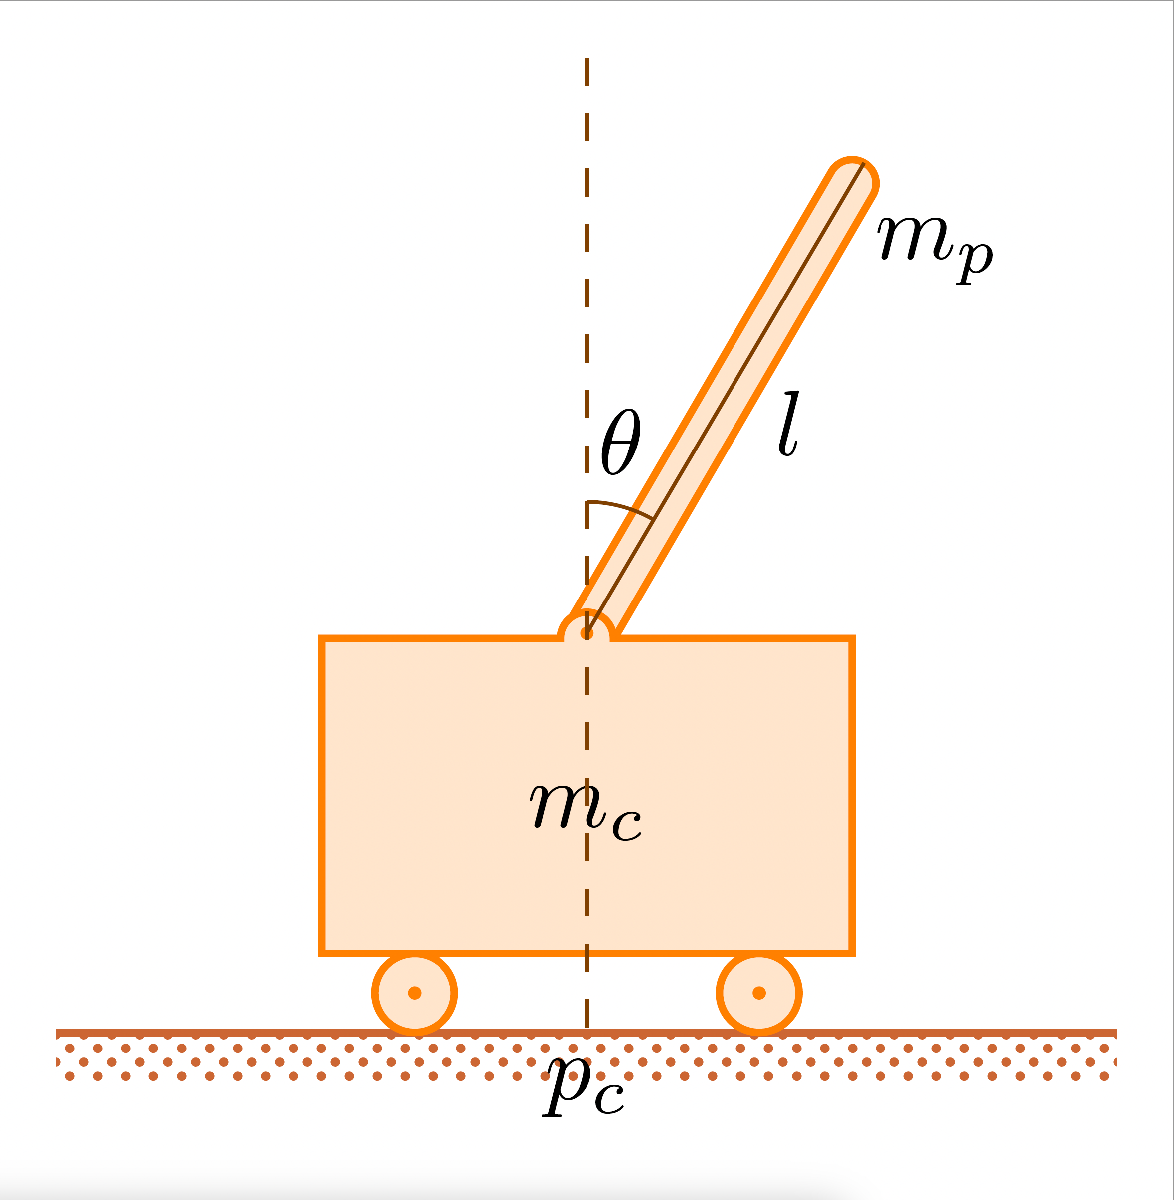

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]\,-\,\mu_c*\text{sgn}(\dot{p_c})}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_c = 0.0005$ is the cart on track friction coefficient, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define the state vector $x$ and the control input vector $u$. Define also the domains to which they belong, $X$ and $U$respectively.

**ANSWER 1:**

We define the **state vector** $x$ as:

$x=\left\lbrack \begin{array}{c}
\theta \\
\dot{\theta} \\
p_c \\
\dot{p_c } 
\end{array}\right\rbrack \in R^{\;4}$    with      $\begin{array}{l}
\theta \;:=\textrm{pole}\;\textrm{angle}\\
\dot{\theta} \;:=\textrm{angular}\;\textrm{velocity}\;\textrm{of}\;\textrm{the}\;\textrm{pole}\\
p_c :=\textrm{cart}\;\textrm{position}\\
\dot{p_c } :=\textrm{cart}\;\textrm{speed}
\end{array}$ 

while the **control input vector** $u$ is nothing more than a scalar between -10 and +10:

$u\in R$    with    $u\in \left\lbrack -10,10\right\rbrack$.

We therefore define the **domain of the state** $X$:


$$X=\left\lbrace x=\left\lbrack \begin{array}{c}
\theta \\
\dot{\theta} \\
p_c \\
\dot{p_c } 
\end{array}\right\rbrack \;\in R^{\;4} \;\textrm{such}\;\textrm{that}\;|\theta |\le \frac{\pi }{2},|\dot{\theta} |\le 20,|p_c |\le 3,|\dot{p_c |} \le 5\right\rbrace$$


while the **control input domain** $U$, will be:

$U=\left\lbrace u\in R\;\textrm{such}\;\textrm{that}\;u\in \left\lbrack -10,10\right\rbrack \right\rbrace$.

OBS.

Let's describe the various limits:

- **Pole angle limit** $\theta$: we consider the experiment "a failure" once the pole falls beyond 90°, i.e. it falls horizontally. We do not consider the possibility of having an angle $\pm \pi$.

- **Angular velocity limit**  $\dot{\theta}$: a velocity greater than 20 rad/s is considered numerically unrealistic, so the experiment will be interrupted in this case.

- **Cart position limit **$p_c$: we consider a work surface with a length of 6 m, therefore the cart can move a maximum of 3 m to the right or 3 m to the left.

- **Cart speed limit** $\dot{p_c }$: we consider a cart with a maximum speed of 5 m/s.

We will now proceed to write MATLAB code in which we will specify the parameters and equations presented in the exercise, clarifying through appropriate comments how they have been defined by us `(e.g. m_c = cart mass, ...)`.

clear 
close all
clc

% We define VARIABLES and PARAMETERS through SYMBOLIC declaration.
syms theta theta_1 p_c p_c_1 p_0
syms g m_c m_p l mu_c mu_p  F

% theta, theta_1 = angle and angular velocity of the pole
% p_c, p_c_1 = position and velocity of the cart
% theta_2, p_c_2 = accelerations appearing in the equations of state

% m_c = cart mass
% m_p = pole mass
% l = half arm length
% g = acceleration due to gravity
% mu_c = cart friction
% mu_p = pole friction
% u = input (i.e. force F)
% p_0 = initial cart position

% expressions of theta_2 and p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);

% --- definition of STATE and INPUT VECTOR, and related DOMAINS ---
x = [theta ; theta_1 ; p_c ; p_c_1];
u = F;

% X = { (theta, theta_1, p_c, p_c_1)' : |theta| <= pi/2, |theta_1| <= 20, |p_c| <= 3, |p_c_1| <= 5 }
% OBS. --> in particular, we limit the angle of the pole so that it can
%          only move pi/2 from the centre, i.e. from when it is in a straight position
assume(abs(theta) <= pi/2);
assume(abs(theta_1) <= 20);
assume(abs(p_c) <= 3);
assume(abs(p_c_1) <= 5);

% U = { u ∈ R : u ∈ [-10, +10] }
% OBS. --> the domain of the control input is defined in the exercise text
assume(abs(F)<=10); 

2. Compute the equilibrium state $$\bar{x}$$ when the control input $$\bar{u}$$ is set equal to $$0$$.

**ANSWER 2:**

Let us calculate the equilibrium states $$\bar{x}$$ considering the control input $$\bar{u}$$ to be zero: we therefore set the derivatives of the system equal to zero and replace the value of the control input with zero. 

We therefore obtain that the equilibrium states for $u=0$ will be: 

$\bar{x} =\left\lbrack \begin{array}{c}
k*\pi \\
0\\
p_0 \\
0
\end{array}\right\rbrack$ where $k\in Z$ e $p_0 \in R\;\textrm{such}\;\textrm{that}\;{|p}_0 |\le 1$ is the starting position from which we start the cart.

Therefore, solving the equilibrium equations, we obtain infinite solutions due to the fact that the angle $\theta =k\pi$. However, considering the state domain $X$ defined in the previous point, and in particular the constraint placed on the angle $|\theta |\le \frac{\pi }{2}$, the only admissible equilibrium point for the system under consideration is the **unstable equilibrium** (as we will see below) in which the pole is in a vertical position:

$\bar{x} =\left\lbrack \begin{array}{c}
0\\
0\\
p_0 \\
0
\end{array}\right\rbrack$    with    $p_0 \in R\;\textrm{such}\;\textrm{that}\;{|p}_0 |\le 1$

Let us now proceed with writing the MATLAB code where we will specify the values of the parameters presented in the exercise, then impose the equilibrium conditions to obtain the above results.

% we define the parameters theta_2_par and p_c_2_par
theta_2_par = subs(theta_2, [g, m_c, m_p, l, mu_c, mu_p], [9.8, 1, 0.1, 0.5, 0.0005, 0.000002]);
p_c_2_par = subs(p_c_2, [g, m_c, m_p, l, mu_c, mu_p], [9.8, 1, 0.1, 0.5, 0.0005, 0.000002]);

% we impose the condition of EQUILIBRIUM, i.e. all DERIVATIVES are ZERO and u = 0
theta_2_eq = subs(theta_2_par, [p_c_1, theta_1, p_c_2, F], [0, 0, 0, 0]);
p_c_2_eq = subs(p_c_2_par, [p_c_1, theta_1, theta_2, F], [0, 0, 0, 0]);

% let's simplify
theta_2_eq = simplify(theta_2_eq);
p_c_2_eq = simplify(p_c_2_eq);

% let's impose theta_2_eq == 0 and solve for theta.
theta_sol = solve(theta_2_eq == 0, theta, "ReturnConditions", true) 

theta_sol = struct with fields:
         theta: pi*z1
    parameters: z1
    conditions: sin(pi*z1) ~= -(3^(1/2)*41^(1/2)*1i)/3 & sin(pi*z1) ~= (3^(1/2)*41^(1/2)*1i)/3 & z1 == 0


3. Given the sequence of control inputs $$\left[u^{(0)},\,u^{(1)},\cdots,u^{(100)}\right]=\left[\right]$$ simulate the behaviour of the non linear system $$(*)$$

**ANSWER 3:**

Let us define a random input sequence and simulate the dynamic system defined above. We consider three different configurations, which differ in their **initial conditions**, while keeping the sampling time unchanged so that we can better compare the three cases:

    `A`**)    **`x0 = [0.05; 0; 0; 0]    and`    `Ts = 0.05`

    `B`**) **   `x0 = [0.20; 0; 0; 0]    and`    `Ts = 0.05`

`  C`**)    **`x0 = [0.60; 0; 0; 0]    and`    `Ts = 0.05`

OBS.

The animations only show the last moment of the simulation. To view the entire simulation, open the corresponding **mp4 files**, which are indicated below each animation.

% let's define the PHYSICAL PARAMETERS
par.g = 9.8;           % Acceleration due to gravity (m/s^2)
par.m_c = 1.0;         % Mass of the cart (kg)
par.m_p = 0.1;         % Mass of the pole (kg)
par.l = 0.5;           % Half the length of the pole (m)
par.mu_c = 0.0005;     % Cart friction
par.mu_p = 0.000002;   % Pole friction

% let us define the CONTROL INPUTS and LIMITS
N = 100;              % Number of control inputs to apply
u_seq = randn(N,1);   % Vector that will contain the random sequence of inputs

theta_max = pi/2;     % |theta| <= pi/2
theta_1_max = 20;     % |theta_1| <= 20
p_c_max = 3;          % |p_c| <= 3
p_c_1_max = 5;        % |p_c_1| <= 5

% --- --- ---

opts = odeset('RelTol',1e-6,'AbsTol',1e-8); 
% This command creates a structure of options to pass to ode45. 

% Specifically:
   
    % RelTol --> controls the relative precision with which the solver accepts the integration error
    % 1e-6 : means that the relative error must be below this value
    % AbsTol --> controls the minimum absolute precision when the variables have small values or values close to zero
    % 1e-8 : means that even when the state is close to zero, the solver will not allow errors greater than this value

% Therefore, odeset causes MATLAB to simulate with high precision by limiting
% both the relative error (with respect to the size of the variables) and
% the absolute error (when the variables are very small)

% --- --- ---

`CASE A) ``x0 = [0.05; 0; 0; 0]    and    Ts = 0.05`

% Let's define the SIMULATION PARAMETERS (case A)
Ts_A = 0.05;          % Duration of each control interval (s)
T_sim_tot_A = Ts_A*N; % Total duration of the simulation (s)


% --- SIMULATION ---

% initial state
x0_A = [0.05; 0; 0; 0];    % [rad; rad/s; m; m/s]

% Initialisation of vectors used to store complete results
t_tot_A = 0;
x_att_A = x0_A;    % The state will be updated at each iteration
x_tot_A = x_att_A;

% START OF SIMULATION
for k = 1:N
    
    % control input for the current range
    par.F = u_seq(k);
    
    % we define the time interval for each iteration
    t_start = (k-1)*Ts_A;
    t_end = k*Ts_A;
    t_span = linspace(t_start, t_end);

    % we run the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_att_A, opts);

    % once the simulation is complete, we update the initial state and then move on to the next segment.
    x_att_A = x_k(end,:)';

    % let's concatenate the results
    t_tot_A = [t_tot_A , t_k(end)];
    x_tot_A = [x_tot_A , x_att_A];
    
    % limit control: if exceeded, stop the simulation
    % 1. control over the angle of the pole
    if (abs(x_att_A(1)) > theta_max)
        warning('Pole angle limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end
    
    % 2. control over the angular velocity of the pole
    if (abs(x_att_A(2)) > theta_1_max)
        warning('Pole angular speed limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

    % 3. control over the position of the cart
    if (abs(x_att_A(3)) > p_c_max)
        warning('Cart position limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

    % 4. control over cart speed
    if (abs(x_att_A(4)) > p_c_1_max)
        warning('Cart speed limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

end

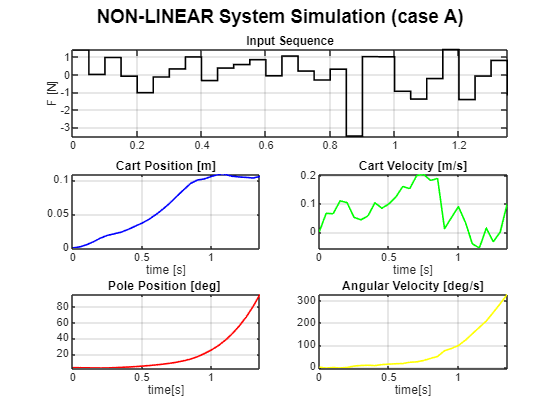


% DISPLAY OF RESULTS
figure;

sgtitle('NON-LINEAR System Simulation (case A)', 'FontWeight', 'bold');

if k==N
    subplot(3,2,1:2);
    stairs(t_tot_A(1:N), u_seq, 'k', 'LineWidth', 1.2);
    ylabel('F [N]'); title('Input Sequence');
    grid on;
    axis tight;
else
    subplot(3,2,1:2);
    stairs(t_tot_A, u_seq(1:k+1), 'k', 'LineWidth', 1.2);
    ylabel('F [N]'); title('Input Sequence');
    grid on;
    axis tight;
end

subplot(3,2,3);
plot(t_tot_A, x_tot_A(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot_A, x_tot_A(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot_A, rad2deg(x_tot_A(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot_A, rad2deg(x_tot_A(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_NL_A ...
Video saved as: animation_NL_A


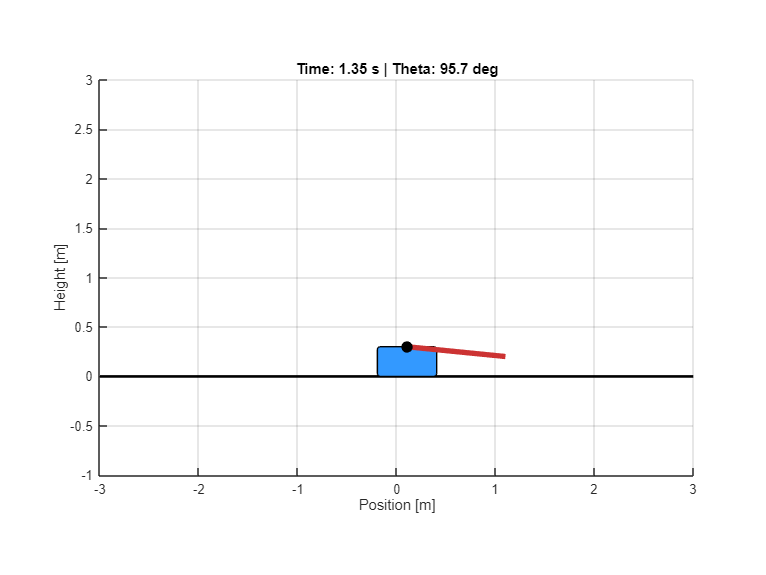

% ANIMATION OF RESULTS --> case A
animazione_test(x_tot_A, par, Ts_A, 'animation_NL_A')

`CASO B) ``x0 = [0.20; 0; 0; 0]    and`    `Ts = 0.05`

% Let's define the SIMULATION PARAMETERS (case B)   
Ts_B = 0.05;          % Duration of each control interval (s)
T_sim_tot_B = Ts_B*N; % Total duration of the simulation (s)



% --- SIMULATION ---

% initial state
x0_B = [0.20; 0; 0; 0];    % [rad; rad/s; m; m/s]

% initialisation of vectors used to store complete results
t_tot_B = 0;
x_att_B = x0_B;    % the state will be updated with each iteration.
x_tot_B = x_att_B;

% START OF SIMULATION
for k = 1:N
    % control input for the current interval
    par.F = u_seq(k);

    % we define the time interval for each iteration
    t_start = (k-1)*Ts_B;
    t_end = k*Ts_B;
    t_span = linspace(t_start, t_end);

    % we run the simulation for the kth segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_att_B, opts);

    % once the simulation is complete, we update the initial state and then move on to the next segment.
    x_att_B = x_k(end,:)';

    % let's concatenate the results
    t_tot_B = [t_tot_B , t_k(end)];
    x_tot_B = [x_tot_B , x_att_B];
    
    % limit control: if exceeded, stop the simulation
    % 1. control over the angle of the pole
    if (abs(x_att_B(1)) > theta_max)
        warning('Pole angle limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end
    
    % 2. control over the angular velocity of the pole
    if (abs(x_att_B(2)) > theta_1_max)
        warning('Pole angular speed limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

    % 3. control over the position of the cart
    if (abs(x_att_B(3)) > p_c_max)
        warning('Cart position limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

    % 4. control over cart speed
    if (abs(x_att_B(4)) > p_c_1_max)
        warning('Cart speed limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

end

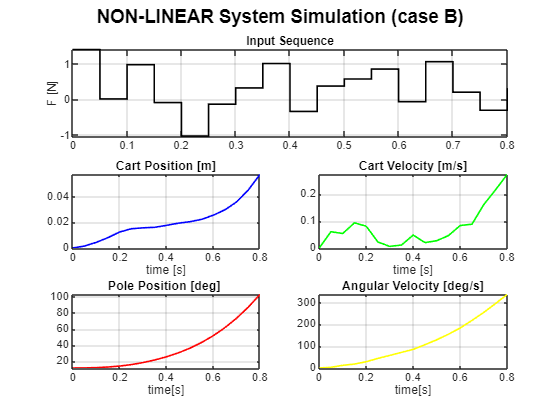


% DISPLAY OF RESULTS
figure;
sgtitle('NON-LINEAR System Simulation (case B)', 'FontWeight', 'bold');

if k==N
    subplot(3,2,1:2);
    stairs(t_tot_B(1:N), u_seq, 'k', 'LineWidth', 1.2);
    ylabel('F [N]'); title('Input Sequence');
    grid on;
    axis tight;
else
    subplot(3,2,1:2);
    stairs(t_tot_B, u_seq(1:k+1), 'k', 'LineWidth', 1.2);
    ylabel('F [N]'); title('Input Sequence');
    grid on;
    axis tight;
end

subplot(3,2,3);
plot(t_tot_B, x_tot_B(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot_B, x_tot_B(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot_B, rad2deg(x_tot_B(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot_B, rad2deg(x_tot_B(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_NL_B ...
Video saved as: animation_NL_B


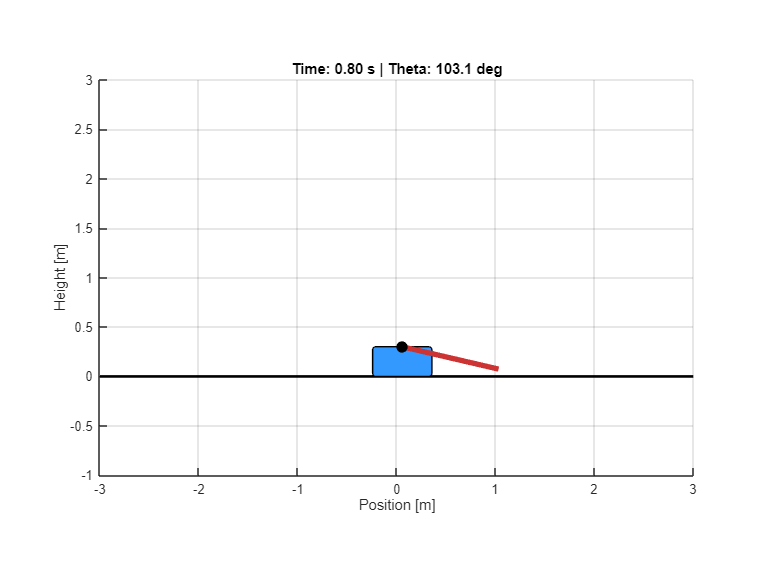

% ANIMATION OF RESULTS --> case B
animazione_test(x_tot_B, par, Ts_B, 'animation_NL_B')

`CASO C) ``x0 = [0.60; 0; 0; 0]    and`    `Ts = 0.05`

% Let's define the SIMULATION PARAMETERS 
Ts_C = 0.05;           % duration of each control interval (s)
T_sim_tot_C = Ts_C*N;  % total duration of the simulation (s)

% --- SIMULATION ---

% initial state
x0_C = [0.60; 0; 0; 0];    % [rad; rad/s; m; m/s]

% Initialisation of vectors used to store complete results
t_tot_C = 0;
x_att_C = x0_C;    % The state will be updated with each iteration.
x_tot_C = x_att_C;


% START OF SIMULATION
for k = 1:N
    % Control input for the current interval
    par.F = u_seq(k);

    % we define the time interval for each iteration
    t_start = (k-1)*Ts_C;
    t_end = k*Ts_C;
    t_span = linspace(t_start, t_end);

    % we run the simulation for the k-th segment
    [t_k, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x_att_C, opts);

    % once the simulation is complete, we update the initial state and then move on to the next segment.
    x_att_C = x_k(end,:)';

    % let's concatenate the results.
    t_tot_C = [t_tot_C , t_k(end)];
    x_tot_C = [x_tot_C , x_att_C];
    
    % limit control: if exceeded, stop the simulation
    % 1. control over the angle of the pole
    if (abs(x_att_C(1)) > theta_max)
        warning('Pole angle limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end
    
    % 2. control over the angular velocity of the pole
    if (abs(x_att_C(2)) > theta_1_max)
        warning('Pole angular speed limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

    % 3. control over the position of the cart
    if (abs(x_att_C(3)) > p_c_max)
        warning('Cart position limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end

    % 4. control over cart speed
    if (abs(x_att_C(4)) > p_c_1_max)
        warning('Cart speed limits exceeded during input equal to %d: simulation stopped.', k);
        break;  % exit the for
    end
end

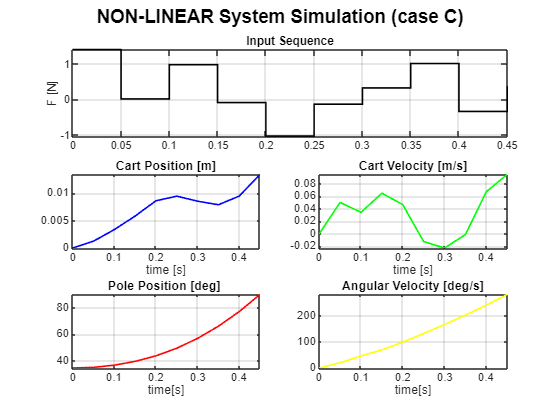


% DISPLAY OF RESULTS
figure;
sgtitle('NON-LINEAR System Simulation (case C)', 'FontWeight', 'bold');

if k==N
    subplot(3,2,1:2);
    stairs(t_tot_C(1:N), u_seq, 'k', 'LineWidth', 1.2);
    ylabel('F [N]'); title('Input Sequence');
    grid on;
    axis tight;
else
    subplot(3,2,1:2);
    stairs(t_tot_C, u_seq(1:k+1), 'k', 'LineWidth', 1.2);
    ylabel('F [N]'); title('Input Sequence');
    grid on;
    axis tight;
end

subplot(3,2,3);
plot(t_tot_C, x_tot_C(3,:), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot_C, x_tot_C(4,:), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot_C, rad2deg(x_tot_C(1,:)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot_C, rad2deg(x_tot_C(2,:)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_NL_C ...
Video saved as: animation_NL_C


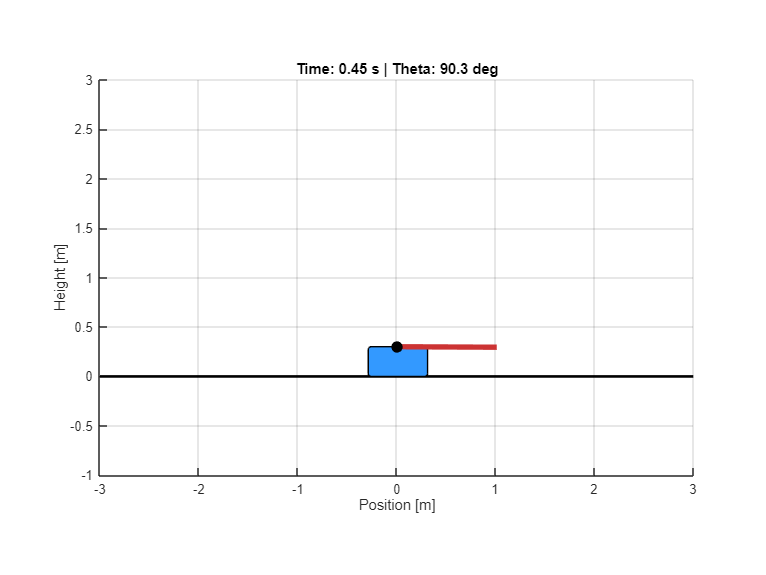

% ANIMATION OF RESULTS --> case C
animazione_test(x_tot_C, par, Ts_C, 'animation_NL_C')

OBS.

Analysis of the trajectory graphs clearly shows the **unstable nature** of the vertical equilibrium point. 

Even in case A, where the initial disturbance is minimal, we note that the angle of the pendulum diverges exponentially over time. 

The trajectory of the state rapidly tends towards infinity (or rather, towards the physical limits of the system), confirming what we will see below, namely that the eigenvalues of the dynamic matrix of the linearised system have a positive real part.

As we can see from the graphs, the speed increases proportionally to the distance from the equilibrium condition.

4. Given the non linear system $(\ast )$ linearize it around the equilibrium point computed in the point 2 and simulate the behaviour of the linear systems given the same sequence of control inputs of point 3.

**ANSWER 4:**

Let us consider the **unstable equilibrium point** corresponding to:


$$\left(\bar{x} ,\bar{u} \right)\;\;\textrm{such}\;\textrm{that}\;\;\bar{x} ={\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0
\end{array}\right\rbrack }^T \;;\;\bar{u} =0$$


So let's analyse the behaviour of the linearised system around $\bar{x}$ in the three different cases defined above (indicated by the letters `A, B, C`).

OBS.

We have considered as the initial position of the cart $p_0 =0$ 

Let's proceed with writing the MATLAB code, in which we will first define the stability of the equilibrium point and then analyse the behaviour of the corresponding linear system in the three different cases.

% CALCULATION OF JACOBIAN MATRICES

% x = [theta ; theta_1 ; p_c ; p_c_1];
% u = F;

% Let us define the state function f(x,u)

% NOTE --> for linearisation, we ignore friction (mu_c, mu_p)
%          because the sign() term is not differentiable at the origin.
theta_2_lin = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta))/(m_c+m_p))) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2_lin = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2_lin)*cos(theta)) ) / (m_c+m_p);

f = [theta_1; theta_2_lin; p_c_1; p_c_2_lin];

% We calculate the Jacobian matrices A and B in symbolic form.
A_sym = jacobian(f, x);
B_sym = jacobian(f, F);

% We define the simulation time interval and the input sequence (for each case)
t_sim_vec_A = t_tot_A;
t_sim_vec_B = t_tot_B;
t_sim_vec_C = t_tot_C;
u_sim_vec_A = u_seq(1:length(t_sim_vec_A)); 
u_sim_vec_B = u_seq(1:length(t_sim_vec_B)); 
u_sim_vec_C = u_seq(1:length(t_sim_vec_C));    

% --- STABILITY ANALYSIS ---
% Equilibrium point: x_bar = [0; 0; 0; 0], u_bar = 0
x_bar = [0; 0; 0; 0];
u_bar = 0;

% Let us substitute the numerical values of the parameters (par) and the equilibrium point
A_num = subs(A_sym, [g, m_c, m_p, l], [par.g, par.m_c, par.m_p, par.l]);
A_num = double(subs(A_num, [x; F], [x_bar; u_bar]));

B_num = subs(B_sym, [g, m_c, m_p, l], [par.g, par.m_c, par.m_p, par.l]);
B_num = double(subs(B_num, [x; F], [x_bar; u_bar]));

% CREATION OF THE LINEAR MODEL
C = eye(4);
D = zeros(4,1);

sys_lin = ss(A_num, B_num, C, D);

% STABILITY of the equilibrium point
if real(eig(A_num))<0
   fprintf("The equilibrium point [%d, %d, %d, %d] is asymptotically stable.", x_bar(1), x_bar(2), x_bar(3), x_bar(4));
elseif real(eig(A_num))==0
   fprintf("The equilibrium point [%d, %d, %d, %d] is simply stable.", x_bar(1), x_bar(2), x_bar(3), x_bar(4));
else
   fprintf("The equilibrium point [%d, %d, %d, %d] is unstable.", x_bar(1), x_bar(2), x_bar(3), x_bar(4));
end

The equilibrium point [0, 0, 0, 0] is unstable.

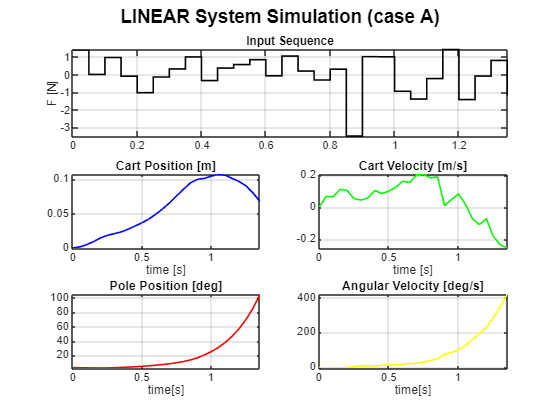


% --- SIMULATION of the linearised system at the equilibrium point ---

% Let us simulate the linear system in three different cases:
[y_lin_A, t_lin_A, x_lin_A] = lsim(sys_lin, u_sim_vec_A, t_sim_vec_A, x0_A); % caso A
[y_lin_B, t_lin_B, x_lin_B] = lsim(sys_lin, u_sim_vec_B, t_sim_vec_B, x0_B); % caso B
[y_lin_C, t_lin_C, x_lin_C] = lsim(sys_lin, u_sim_vec_C, t_sim_vec_C, x0_C); % caso C

% Display of linear simulation results --> case A
figure;
sgtitle("LINEAR System Simulation (case A)", 'FontWeight', 'bold');

subplot(3,2,1:2);
stairs(t_lin_A, u_sim_vec_A, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_lin_A, x_lin_A(:,3), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_lin_A, x_lin_A(:,4), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_lin_A, rad2deg(x_lin_A(:,1)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg]');
grid on;
axis tight;

subplot(3,2,6);
plot(t_lin_A, rad2deg(x_lin_A(:,2)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_LIN_A ...
Video saved as: animation_LIN_A


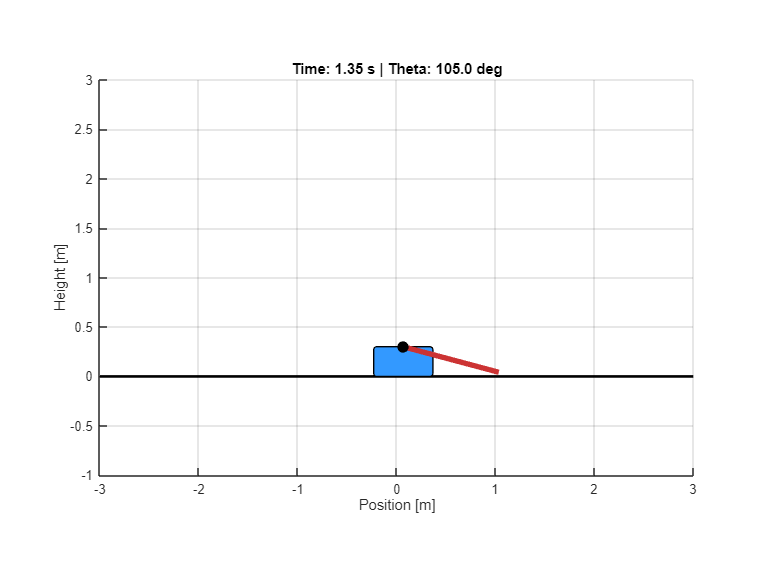

% ANIMATION OF RESULTS --> case A
animazione_test(x_lin_A', par, Ts_A, 'animation_LIN_A')

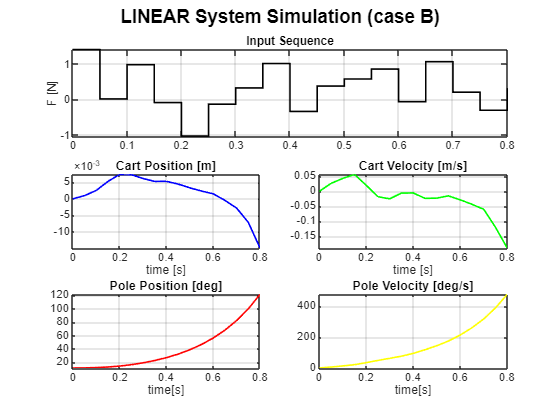

% Display of linear simulation results --> case B
figure;
sgtitle('LINEAR System Simulation (case B)', 'FontWeight', 'bold');

subplot(3,2,1:2);
stairs(t_lin_B, u_sim_vec_B, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_lin_B, x_lin_B(:,3), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_lin_B, x_lin_B(:,4), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_lin_B, rad2deg(x_lin_B(:,1)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg]');
grid on;
axis tight;

subplot(3,2,6);
plot(t_lin_B, rad2deg(x_lin_B(:,2)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_LIN_B ...
Video saved as: animation_LIN_B


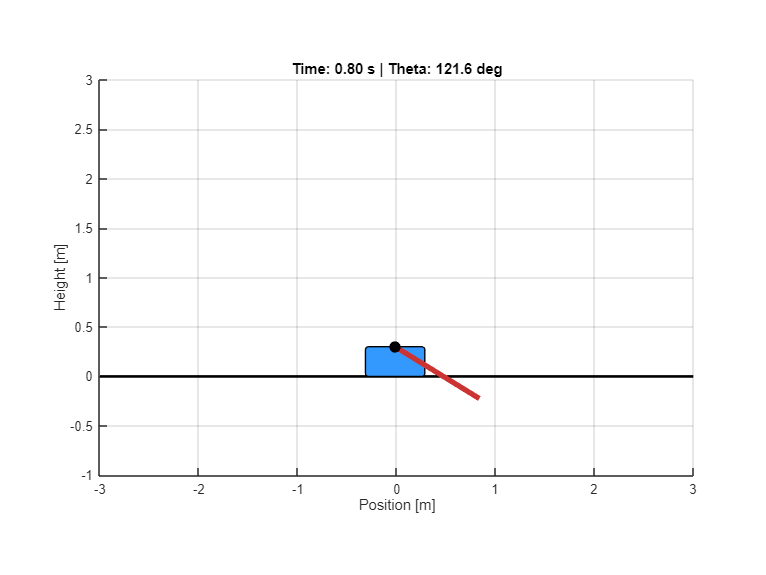

% ANIMATION OF RESULTS --> case B
animazione_test(x_lin_B', par, Ts_B, 'animation_LIN_B')

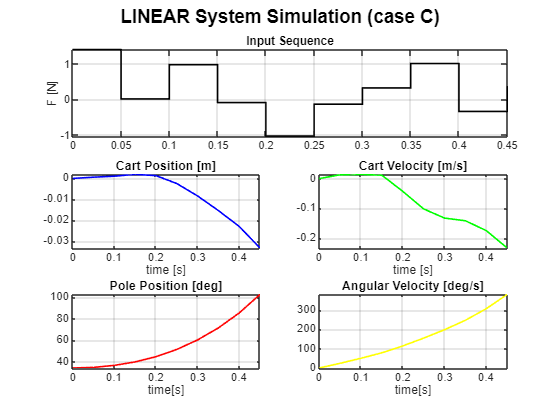

% Display of linear simulation results --> case C
figure;
sgtitle('LINEAR System Simulation (case C)', 'FontWeight', 'bold');

subplot(3,2,1:2);
stairs(t_lin_C, u_sim_vec_C, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_lin_C, x_lin_C(:,3), 'b', 'LineWidth', 1.2); 
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_lin_C, x_lin_C(:,4), 'g', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_lin_C, rad2deg(x_lin_C(:,1)), 'r', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg]');
grid on;
axis tight;

subplot(3,2,6);
plot(t_lin_C, rad2deg(x_lin_C(:,2)), 'y', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

Start video recording: animation_LIN_C ...
Video saved as: animation_LIN_C


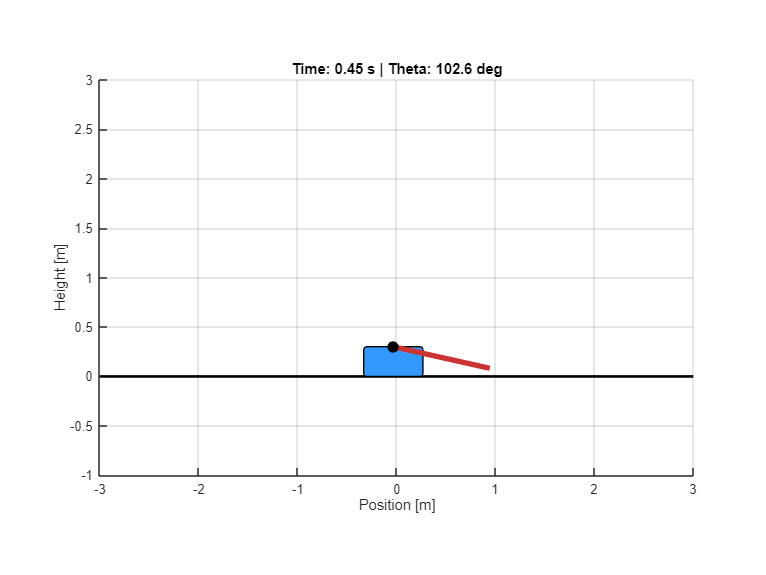

% ANIMATION OF RESULTS --> case C
animazione_test(x_lin_C', par, Ts_C, 'animation_LIN_C')

5. Comment the results obtained in point 3 and 4. Do you observe any difference?

**ANSWER 5:**

Now let's **compare** the results obtained in the non-linear system *(continuous line)* with those of the linearised system *(dotted line)* around the equilibrium point $\left(\bar{x} ,\bar{u} \right)$ starting from the initial conditions closest to equilibrium, i.e. those of case A, then moving on to case B, and then to case C.

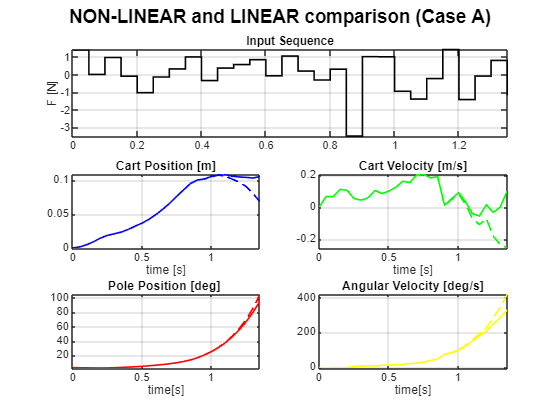

% Comparison between NON-LINEAR and LINEAR systems --> CASE A
figure;

sgtitle('NON-LINEAR and LINEAR comparison (Case A)', 'FontWeight', 'bold');

subplot(3,2,1:2);
stairs(t_lin_A, u_sim_vec_A, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_tot_A, x_tot_A(3,:), 'b', 'LineWidth', 1.2); 
hold on;
plot(t_lin_A, x_lin_A(:,3), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot_A, x_tot_A(4,:), 'g', 'LineWidth', 1.2);  
hold on;
plot(t_lin_A, x_lin_A(:,4), 'g--', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot_A, rad2deg(x_tot_A(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t_lin_A, rad2deg(x_lin_A(:,1)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot_A, rad2deg(x_tot_A(2,:)), 'y', 'LineWidth', 1.2); 
hold on;
plot(t_lin_A, rad2deg(x_lin_A(:,2)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

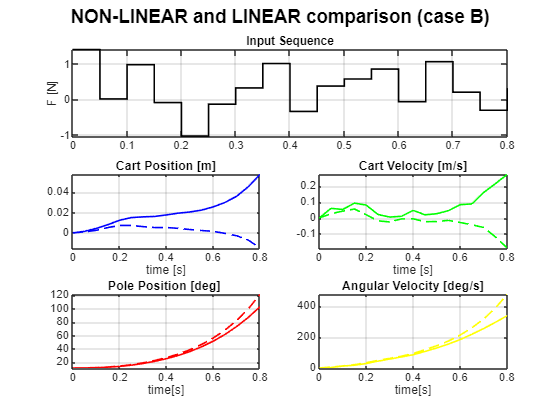


% Comparison between NON-LINEAR and LINEAR systems --> CASE B
figure;

sgtitle('NON-LINEAR and LINEAR comparison (case B)', 'FontWeight', 'bold');

subplot(3,2,1:2);
stairs(t_lin_B, u_sim_vec_B, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_tot_B, x_tot_B(3,:), 'b', 'LineWidth', 1.2); 
hold on;
plot(t_lin_B, x_lin_B(:,3), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot_B, x_tot_B(4,:), 'g', 'LineWidth', 1.2);  
hold on;
plot(t_lin_B, x_lin_B(:,4), 'g--', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot_B, rad2deg(x_tot_B(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t_lin_B, rad2deg(x_lin_B(:,1)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot_B, rad2deg(x_tot_B(2,:)), 'y', 'LineWidth', 1.2); 
hold on;
plot(t_lin_B, rad2deg(x_lin_B(:,2)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

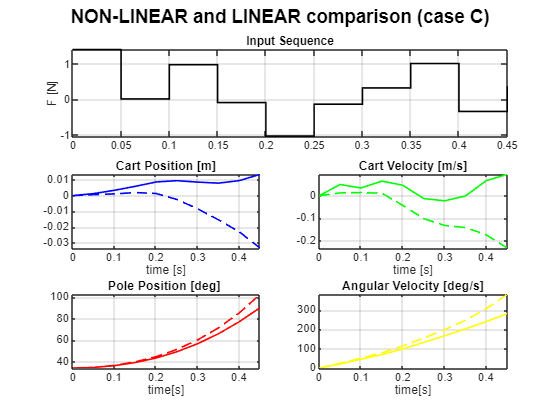


% Comparison between NON-LINEAR and LINEAR systems --> CASE C
figure;

sgtitle('NON-LINEAR and LINEAR comparison (case C)', 'FontWeight', 'bold');

subplot(3,2,1:2);
stairs(t_lin_C, u_sim_vec_C, 'k', 'LineWidth', 1.2);
ylabel('F [N]'); title('Input Sequence');
grid on;
axis tight;

subplot(3,2,3);
plot(t_tot_C, x_tot_C(3,:), 'b', 'LineWidth', 1.2); 
hold on;
plot(t_lin_C, x_lin_C(:,3), 'b--', 'LineWidth', 1.2);
xlabel('time [s]'); title('Cart Position [m]');
grid on;
axis tight;

subplot(3,2,4);
plot(t_tot_C, x_tot_C(4,:), 'g', 'LineWidth', 1.2);  
hold on;
plot(t_lin_C, x_lin_C(:,4), 'g--', 'LineWidth', 1.2);  
xlabel('time [s]'); title('Cart Velocity [m/s]');
grid on;
axis tight;

subplot(3,2,5);
plot(t_tot_C, rad2deg(x_tot_C(1,:)), 'r', 'LineWidth', 1.2); 
hold on;
plot(t_lin_C, rad2deg(x_lin_C(:,1)), 'r--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Pole Position [deg] ');
grid on;
axis tight;

subplot(3,2,6);
plot(t_tot_C, rad2deg(x_tot_C(2,:)), 'y', 'LineWidth', 1.2); 
hold on;
plot(t_lin_C, rad2deg(x_lin_C(:,2)), 'y--', 'LineWidth', 1.2); 
xlabel('time[s]'); title('Angular Velocity [deg/s]');
grid on;
axis tight;

OBS.

From the graphical comparison of the trajectories between the real system (non-linear) and the linearised one, we observe that:

- **Case A (small perturbation)**: with an initial condition close to equilibrium $\left(0\ldotp 05\;\textrm{rad}\approx 2\ldotp 86\degree \right)$, the two trajectories are almost superimposed. The linearised system, therefore, provides an excellent approximation of the real dynamics.

- **Cases B and C (large perturbations)**: moving away from equilibrium $\left(\textrm{case}\;B\;\textrm{with}\;0\ldotp 20\;\textrm{rad}\approx 11\ldotp 46\degree ,\textrm{case}\;C\;\textrm{with}\;0\ldotp 60\;\textrm{rad}\approx 34\ldotp 38\degree \right)$, the linear model presents a more significant estimation error, greater in C than in B. This shows us that control based on the linear model will only be effective if the system is kept within a very narrow range of the equilibrium point.

**NOTE:**

*Local Functions* used in the above code, presented with appropriate comments:

% --- LOCAL FUNCTION ---
% % 1. dinamica_nonLineare() --> allows us to calculate x_dot, through the implementation
%                                of the nonlinear differential equations of the Cart-and-Pole system. 
%                                The parameters we will pass are:
%                                   - t, not used explicitly in the function, is used to call ode()
%                                   - x, state vector [4x1]
%                                   - par, a structure containing all useful parameters

function dxdt = dinamica_nonLineare(t, x, par)

% extraction of parameters and state
g = par.g;
m_c = par.m_c;
m_p = par.m_p;
l = par.l;
mu_c = par.mu_c;
mu_p = par.mu_p;
F = par.F;

theta    = x(1);
theta_1  = x(2);
p_c      = x(3);
p_c_1    = x(4);

% we therefore define theta_2 and p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);


% let's define the derivative vector dxdt
% dxdt = [theta_1; theta_2; p_c_1; p_c_2]
dxdt = zeros(4, 1);

dxdt(1) = theta_1;
dxdt(2) = theta_2;
dxdt(3) = p_c_1;
dxdt(4) = p_c_2;

end

% % 2. animazione_test() --> allows us to describe the animation of the cart-and-pole system, 
%                            thus providing visual support in addition to the graphs.
%                            It only shows the last moment in time, but this function allows us to save the various frames
%                            in a video, so that we can see the entire simulation
%                            The parameters we pass to it are:
%                               - stati, a vector containing all states 
%                               - par, a struct containing all useful parameters
%                               - Ts, sampling time
%                               - video_filename, the name we saved the video file with

function animazione_test(stati, par, Ts, video_filename)
    
    % graphical parameters
    L = 2 * par.l;          
    W_cart = 0.6;           
    H_cart = 0.3;           
    
    % let's create the figure
    h_fig = figure('Name', 'Animazione Cart-Pole', 'Color', 'w');
    set(h_fig, 'Position', [100, 100, 800, 600]); 
    clf;
    hold on;
    grid on;
    axis equal;
    xlim([-3, 3]);          
    ylim([-1, 3]); 

    % let's create the 'floor'
    line([-3, 3], [0, 0], 'Color', 'k', 'LineWidth', 2);

    % create a video file in the current folder
    v = VideoWriter(video_filename, 'MPEG-4');
    v.FrameRate = 1/Ts; 
    open(v);
    fprintf('Start video recording: %s ...\n', video_filename);
    
    % let's draw the Initial Condition
    theta0 = stati(1, 1);
    pos0   = stati(3, 1);
    
    % calculation of initial coordinates
    cart_x0 = pos0 - W_cart / 2;
    base_x0 = pos0;
    base_y0 = H_cart;
    punta_x0 = base_x0 + L * sin(theta0);
    punta_y0 = base_y0 + L * cos(theta0);

    % drawing stationary objects
    % OSS. --> - rectangle(), for the cart
    %          - line(), for the pole
    %          - plot(), for the joint, i.e. the junction between them
    h_cart = rectangle('Position', [cart_x0, 0, W_cart, H_cart], 'FaceColor', [0.2, 0.6, 1], 'Curvature', 0.2);
    h_pole = line([base_x0, punta_x0], [base_y0, punta_y0], 'Color', [0.8, 0.2, 0.2], 'LineWidth', 4);
    h_joint = plot(base_x0, base_y0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    
    title_handle = title('Generazione Video in corso... ');
    xlabel('Position [m]');
    ylabel('Height [m]');
   

    % Animation Cycle
    n_steps = size(stati,2);

    for k = 1:n_steps
        
        theta = stati(1, k);
        pos   = stati(3, k);
        
        % Coordinate update
        cart_x = pos - W_cart / 2;   
        set(h_cart, 'Position', [cart_x, 0, W_cart, H_cart]);
        
        base_x = pos;
        base_y = H_cart;
        punta_x = base_x + L * sin(theta);
        punta_y = base_y + L * cos(theta);
        
        set(h_pole, 'XData', [base_x, punta_x], 'YData', [base_y, punta_y]);
        set(h_joint, 'XData', base_x, 'YData', base_y);
        
        set(title_handle, 'String', sprintf('Time: %.2f s | Theta: %.1f deg', (k-1)*Ts, rad2deg(theta)));
        
        % command for drawing the cart-and-pole
        drawnow; 
       
        % FRAME capture and frame loading (in the video)
        frame = getframe(h_fig);
        writeVideo(v, frame);
    end
    
    % Close and save the video file
    close(v);
    fprintf('Video saved as: %s\n', video_filename);
end